# Define Aesthetics and Titles

% Make background grey and have grid lines on
set(0, 'defaultfigurecolor', '#F0F0F0');
set(groot, 'DefaultAxesXGrid', 'on', 'DefaultAxesYGrid', 'on', 'DefaultAxesZGrid', 'on');

% bandLimits = [500, 630; 630, 700; 700, 820; 820, 980; 980, 1080; 1080, 1180; 1180, 1390; 1390, 1480; 1480, 1800]
% Define band properties
% bandColors = parula(6);
bandColors = orderedcolors("meadow");
bandTitles = {"Carbon", "Ozone", "Methane", "Window", "Water", 'Total'};
bandLimits = ["10-350" "350-500" "500-630" "630-700" "700-820" "820-980" "980-1080" "1080-1180" "1180-1390" "1390-1480" "1480-1800" "1800-2080" "2080-2250" "2250-2380" "2380-2600" "2600-3250"];

% Define met titles and titles
metTitles = {"Temperature", "Specific Humidity", "Wind", "ln(SH)"};
metUnits = {'K', 'g/kg', 'm/s', 'g/kg', 'g/kg'};
metVarColours = {'#FEBC2E', '#B40007', '#007B6B', '#95390F', '#3F30B9', '#D694FF'};
metVarTypesTitles = {'Burnside', 'Gault', 'Difference'};
monthTitles = ["June", "July", "August"];
yearTitles = "2024";
chosenColours = {'#007B6B', '#D694FF'};
mtTitles = ["June", "July", "August", "Summer"];

# Define Sat Vap and Kernel Functions

function satVap = sat_vap_from_temp(t) % in kPa
    c1 = 34.494;
    c2 = 4924.99;
    c3 = 237.1; 
    c4 = 105;
    c5 = 1.57;
    % Using the formula of Huang J. 2018, temperature in degrees celcius
    satVap = exp(c1-(c2./(t+c3)))./((t+c4).^c5);
end

function wvLW = WV_LW(wvK, dq, q, es, es1)
    % From Huang & Huang 2023 Copernicus data article
    % Loop through each band
    
    wvLW = zeros(length(dq), length(wvK));

    for i = 1:length(wvK)
        lwi = wvK(i) .* (dq./q) .* es./(es1 - es);
        wvLW(:, i) = lwi;
    end
end

function WLW = S_WV_LW(wvK, dlnq)
        
        WLW = zeros(length(dlnq), length(wvK));
        for i = 1:length(wvK)
            WLW(:, i) = wvK(i) .* dlnq;
        end
end

function TLW = T_LW(tK, dT)
    
    TLW = zeros(length(dT), length(tK));
    for i = 1:length(tK)
    
        TLW(:, i) = tK(i) .* dT;
    end
end

# Import the Vertically Integrated Spectral Kernels

% Import Spectral Kernels
TaDir = '/Users/lukemartin/Documents/MATLAB/ERA5_spectral_kernel_Ta_int.nc';
WVDir = '/Users/lukemartin/Documents/MATLAB/ERA5_spectral_kernel_WV_LW_int.nc';

% Read them (4 dimentions: band_lw, longitude, latitude, month)
TFull = ncread(TaDir, "ta_all_sfc");
TClear = ncread(TaDir, 'ta_clr_sfc');

WFull = ncread(WVDir, "wv_lw_all_sfc");
WClear = ncread(WVDir, "wv_lw_clr_sfc");

# Index for Montreal Grid Cell

% Define limits
lat = round(45.5088/2.5); % All grid cells are 2.5x2.5
long = round(73.5617/2.5);
nM = [6, 7, 8];

% Get the useful parts!
TFullM = TFull(:, long, lat, nM);
TClearM = TClear(:, long, lat, nM);
WFullM = WFull(:, long, lat, nM);
WClearM = WClear(:, long, lat, nM);

% Make into a list
kernels = {TFullM, TClearM, WFullM, WClearM};

# Get met Variables

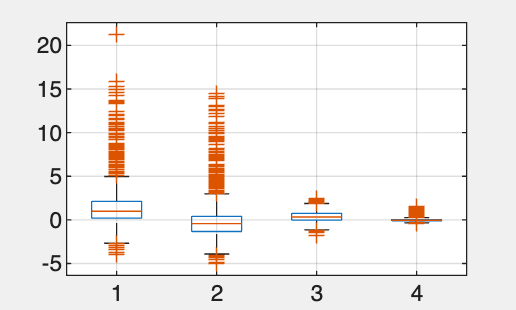

metDirGault = '/Users/lukemartin/Documents/MATLAB/Gault Met Values.csv';
% Get time table
metG = readtimetable(metDirGault);
metTime = unique(metG.Time);
% Synch time table to differences
% metG = synchronize(metG, chosenSky{1}.timeVector);
metG = synchronize(metG, metTime);
% Get variables
T = metG.MeanTemp + 273;
T(T < 280) = NaN;
SH = metG.MeanSH;
SH(SH < 2) = NaN;
W =  metG.Wind;
lnSH = log(SH./1000);
% metVarsG = filloutliers([T, SH, W, lnSH], NaN);
metVarsG = [T, SH, W, lnSH];


% figure
% tiledlayout(2, 2)
% for i = 1:4
%     nexttile
%     hold on
%     histogram(metVarsG(:, i), 'FaceColor', metVarColours{i}, 'FaceAlpha', 0.5)
%     ylabel('Count')
%     xlabel(metTitles{i} + ' (' + metUnits{i} + ')')
%     hold off
% end

metDirMont = '/Users/lukemartin/Documents/MATLAB/Met_Airport_Processed.csv';
% Get time table
metM = readtimetable(metDirMont);
% Synch time table to differences
% metM = synchronize(metM, chosenSky{1}.timeVector);
metM = synchronize(metM, metTime);
% Get variables
T = metM.MeanTemp + 273;
SH = metM.MeanSH;
W =  metM.Wind./10;
lnSH = log(SH./1000);
% metVarsM = filloutliers([T, SH, W, lnSH], NaN);
metVarsM = [T, SH, W, lnSH];

% figure
% tiledlayout(2, 2)
% for i = 1:4
%     nexttile
%     hold on
%     histogram(metVarsM(:, i),  'FaceColor', metVarColours{i}, 'FaceAlpha', 0.5)
%     ylabel('Count')
%     xlabel(metTitles{i} + ' (' + metUnits{i} + ')')
%     hold off
% end

metVarsDiff = metVarsM - metVarsG;

figure
boxplot(metVarsDiff)

diffTT = splitvars(timetable(metTime, metVarsDiff));

startDate = datetime(2024, 6, 17);
endDate = datetime(2024, 6, 20);
hwDT = datetime(startDate:hours(1):endDate);

hwDiff = diffTT(hwDT, :);

Error using  ==  (line 758)
Matrix dimensions must agree.

hwG = metG(hwDT, :);
hwMont = metM(hwDT, :);

nightIdx = find(hour(metTime) <= 7);
n = hwDiff(nightIdx, :);

figure
tiledlayout(1, 2)
for i = 1:2
    nexttile
    hold on
    histogram(n(:, i), 'FaceColor', metVarColours{i}, 'FaceAlpha', 0.5)
    ylabel('Count')
    xlabel(metTitles{i} + ' (' + metUnits{i} + ')')
    hold off
end
% figure
% tiledlayout(2, 2)
% for i = 1:4
%     nexttile
%     hold on
%     histogram(metVarsDiff(:, i), 'FaceColor', metVarColours{i}, 'FaceAlpha', 0.5)
%     ylabel('Count')
%     xlabel(metTitles{i} + ' (' + metUnits{i} + ')')
%     hold off
% end

# Plot by Hour for Each Met Var using Loess

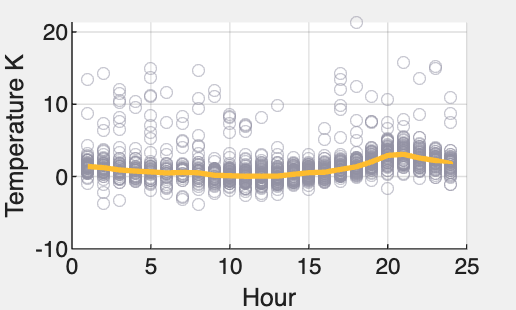

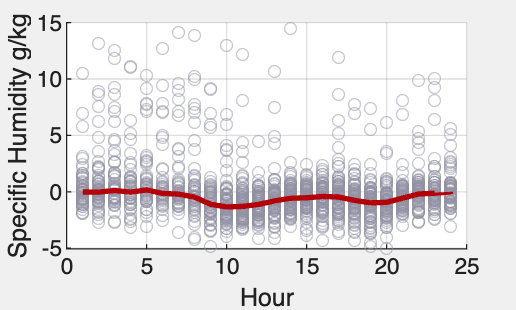

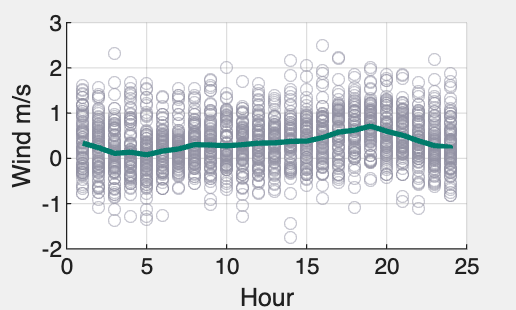

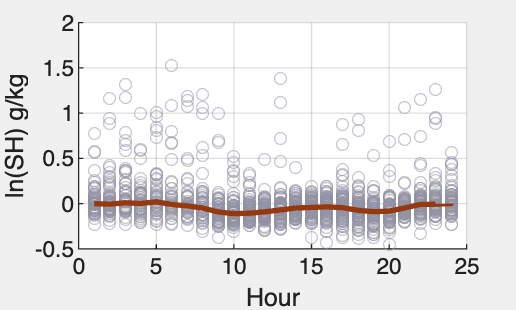

% Choose a sky
h = hour(metTime - hours(4)) + 1;
nIdx = find(h <= 6 | h >= 20);

for i = 1:4
    chosenMet = metVarsDiff(:, i);
    
    % Smooth using robust Loess (to limit effects of outliers)
    loess = smooth(h, chosenMet, 'rloess');

    % Use findpeaks to find local maxima and minima
    [maxima, locs] = findpeaks(loess);

    % Use max and min to get the explicit max and min from findpeaks
    [maximum, locmax] = max(loess);
    [minimum, locmin] = min(loess);

    [sortedh,ind] = sort(h);
    % subplot(2,1,1)
    uniqueh = unique(h);
    plotBand = chosenMet(ind);
    figure
    % Plot the data and the fit
    hold on
    scatter(sortedh, plotBand, 20, 'MarkerEdgeColor', '#9291A3', 'MarkerEdgeAlpha', 0.5)
    plot(sortedh, loess(ind), 'Color', metVarColours{i}, 'LineWidth', 2)
    xlabel("Hour")
    % xticks(1:24)
    % xticklabels(string(uniqueh) + ":00")
    ylabel(string(metTitles{i}) + " " + metUnits{i})
    hold off
    exportgraphics(gcf, "Loess " + string(metTitles{i}) + " Full.png")

    % Plot only loess with max and min as another tile
    % nexttile
    % hold on
    % plot(sortedh, loess(ind), 'Color', bandColors(i,:), 'LineWidth', 2)
    % % Plot the maxima with labels and gold stars
    % plot(locs, maxima, '*', 'Color', '#D39517')
    % text(locmax, maximum, ['(', num2str(locmax), ', ', num2str(maximum), ')'])
    % text(locmin, minimum, ['(', num2str(locmin), ', ', num2str(minimum), ')'])
    % xlabel("Hour")
    % ylabel(bandTitles{i})
    % hold off
    
end

# Complete Kernel Calculations for Each Time

%%%%%%%%%%%%% Clear %%%%%%%%%%%%%%

% Choose a month
mMet = month(metM.timeVector);
uniqueM = unique(mMet);
uniqueM(1) = [];

% Preallocate space for each month
tDLR = cell(1, length(uniqueM));
wDLR = cell(1, length(uniqueM));
wSDLR = cell(1, length(uniqueM));

monthlydT = cell(1, 3);
monthlydW = cell(1, 3);

for i = 1:length(uniqueM)
    % Choose the ERA5 Kernel of Month i
    TK = kernels{2}(:, 1, 1, i);
    WK = kernels{4}(:, 1, 1, i);

    % Choose met values from that month
    mIdx = find(mMet == uniqueM(i));
    dT = metVarsDiff(mIdx, 1);
    dW = metVarsDiff(mIdx, 2);
    dlnW = metVarsDiff(mIdx, 4);

    T = metVarsG(mIdx, 1);
    W = metVarsG(mIdx, 2);

    % As W is in kg/kg, divide by 1000
    dW = dW./1000;
    W = W./1000;

    % Compute the Temperature Kernel Fluxes
    TFluxes = T_LW(TK, dT);

    % Compute Water Vapor Kernel Fluxes
    es = sat_vap_from_temp(T);
    es1 = sat_vap_from_temp(T + 1);

    WVFluxes = WV_LW(WK, dW, W, es, es1);

    sWVFluxes = S_WV_LW(WK, dlnW);

    tDLR{i} = TFluxes;
    wDLR{i} = WVFluxes;
    wSDLR{i} = sWVFluxes;

    monthlydT{i} = dT;
    monthlydW{i} = dW;
end

figure
boxplotGroup(monthlydT)

figure
boxplotGroup(monthlydW)

# Make Plots of Radiative Kernel Estimates

for i = 1:length(uniqueM)
    chosenTk = tDLR{i};
    chosenWk = wDLR{i};

    % Make histograms for each spectral band
    figure
    hold on
    tiledlayout(4, 4)
    for j = 1:16
        nexttile
        hold on
        histogram(chosenTk(:, j),  'FaceColor', metVarColours{3}, 'FaceAlpha', 0.5)
        ylabel('Count')
        xlabel('Flux of ' + bandLimits(j) + ' Band (W/m^2)')
        hold off
    end
    title('Temperature Kernel Fluxes ' + monthTitles(i) + ' ' + yearTitles)
    hold off

    figure
    hold on
    tiledlayout(4, 4)
    for j = 1:16
        nexttile
        hold on
        histogram(chosenWk(:, j),  'FaceColor', metVarColours{5}, 'FaceAlpha', 0.5)
        ylabel('Count')
        xlabel('Flux of ' + bandLimits(j) + ' Band (W/m^2)')
        hold off
    end
    title('Water Vapor Kernel Fluxes ' + monthTitles(i) + ' ' + yearTitles)
    hold off

    % Take the mean of each and plot them
    meanTK = mean(chosenTk, 'omitnan');
    meanWK = mean(chosenWk, 'omitnan');
    means = [meanTK; meanWK];

    chosenColors = [metVarColours{3}; metVarColours{6}];

    figure
    hold on
    % bar(1:16, means, 'FaceAlpha', 0.5)
    bar(1:16, means, 'stacked', 'FaceColor', 'flat', 'FaceAlpha', 0.5)
    xticklabels(bandLimits)
    xlabel("Wavenumber Region (cm^-1)")
    ylabel("Estimated Flux (W/m^2)")
    legend("Temperature", "Water Vapor")
    colororder(chosenColors)
    title(monthTitles(i) + ' ' + yearTitles)
    hold off
end


% Make into one long column
TKTot = [tDLR{1}; tDLR{2}; tDLR{3}];
WKTot = [wDLR{1}; wDLR{2}; wDLR{3}];

TCounts = [sum(~isnan(tDLR{1}), 1); sum(~isnan(tDLR{2}), 1); sum(~isnan(tDLR{3}), 1)];
WCounts = [sum(~isnan(wDLR{1}), 1); sum(~isnan(wDLR{2}), 1); sum(~isnan(wDLR{3}), 1)];

countsMat = [TCounts(:, 1), WCounts(:, 1)];

T1 = mean(tDLR{1}, 'omitnan');
T2 = mean(tDLR{2}, 'omitnan');
T3 = mean(tDLR{3}, 'omitnan');

W1 = mean(wDLR{1}, 'omitnan');
W2 = mean(wDLR{2}, 'omitnan');
W3 = mean(wDLR{3}, 'omitnan');

TTot = [T1; T2; T3];
WTot = [W1; W2; W3];

summerMeanT = mean(TTot, 'omitnan');
summerMeanW = mean(WTot, 'omitnan');

means = [summerMeanT; summerMeanW];

% Make histograms for each spectral band
% figure
% hold on
% tiledlayout(4, 4)
% for j = 1:16
%     nexttile
%     hold on
%     histogram(TKTot(:, j),  'FaceColor', metVarColours{3}, 'FaceAlpha', 0.5)
%     ylabel('Count')
%     xlabel('Flux of ' + bandLimits(j) + ' Band (W/m^2)')
%     hold off
% end
% title('Temperature Kernel Fluxes Summer ' + yearTitles)
% hold off
% 
% figure
% hold on
% tiledlayout(4, 4)
% for j = 1:16
%     nexttile
%     hold on
%     histogram(WKTot(:, j),  'FaceColor', metVarColours{5}, 'FaceAlpha', 0.5)
%     ylabel('Count')
%     xlabel('Flux of ' + bandLimits(j) + ' Band (W/m^2)')
%     hold off
% end
% title('Water Vapor Kernel Fluxes Summer ' + yearTitles)
% hold off

% Bar charts of radiative forcing
% figure
% hold on
% bar(1:16, means, 'stacked', 'FaceColor', 'flat', 'FaceAlpha', 0.5)
% xticklabels(bandLimits)
% xlabel("Wavenumber Region (cm^-1)")
% ylabel("Estimated Flux (W/m^2)")
% legend("Temperature", "Water Vapor")
% colororder(chosenColors)
% title('Summer ' + yearTitles)
% hold off
% exportgraphics(gcf, 'Summer 2024.png')

% % Counts figure
% figure
% hold on
% bar(1:2, countsMat, 'stacked', 'FaceColor', 'flat', 'FaceAlpha', 0.5)
% xticklabels({" ", " ", "Temperature", " ", "Water Vapor"})
% ylabel("Number of Valid Entries")
% legend("June", "July", "August")
% colororder([metVarColours{1}; metVarColours{2}; metVarColours{4}])
% title('Summer ' + yearTitles)
% hold off

# Slope vs. Kernel Comparison

% Import average slopes and wavenumber averaged (DLR - b) values
sT = readmatrix("Temperature Slopes.csv");
sW = readmatrix("Water Slopes.csv");
slnW = readmatrix("lnW Slopes.csv");
cT = readmatrix("Temperature Conversion.csv");
cW = readmatrix("Water Conversion.csv");
clnW = readmatrix("lnW Conversion.csv");
DLRK = readmatrix("DLR Regions.csv");
RMSET = readmatrix("RMSET Regions.csv");
RMSEW = readmatrix("RMSEW Regions.csv");
RMSElnW = readmatrix("RMSElnW Regions.csv");

% Define all kernels in one matrix
Rt = [TTot; summerMeanT];
Rt = Rt(:, 3:11);
Rw = [WTot; summerMeanW];
Rw = Rw(:, 3:11);

avgKT = mean(TClearM, 4);
avgKW = mean(WClearM, 4);

TKern = TClearM(3:11, :, :, :);
WKern = WClearM(3:11, :, :, :);

TKern(:, :, :, end + 1) = avgKT(3:11);
WKern(:, :, :, end + 1) = avgKW(3:11);

% Plot a * (Kernel Flux/(DLR - b)) for each wn range as bar plot
figure
tiledlayout(2, 2)
for i = 1:4
    means = [Rt(i, :) + Rw(i, :); DLRK(i, :)];
    
    nexttile
    hold on
    bar(1:9, means, 'FaceColor', 'flat', 'FaceAlpha', 0.5)
    xticklabels(bandLimits(3:2:11))
    xlabel("Wavenumber Region (cm^-1)")
    ylabel("Estimated Flux (W/m^2)")
    colororder([chosenColors])%; '#B40007'])
    title(mtTitles(i) + " " + string(yearTitles))
    hold off
end
legend("Flux", "DLR")
exportgraphics(gcf, 'Forcing and DLR.png')

% Plot this value next to basic kernel values
figure
tiledlayout(2, 2)
for i = 1:4
    means = [TKern(:, :, :, i)'; sT(i, :)];
    
    nexttile
    hold on
    bar(1:9, means, 'FaceColor', 'flat', 'FaceAlpha', 0.5)

    % Add error bars
    % er = errorbar(1:9, sT(i, :), sT(i, :) - RMSET(i, :), sT(i, :) + RMSET(i, :));   
    % er.Color = [0 0 0];                            
    % er.LineStyle = 'none';  

    xticklabels(bandLimits(3:2:11))
    xlabel("Wavenumber Region (cm^-1)")
    ylabel("Estimated Kernel (W/m^2)")
    colororder(chosenColors)%; '#B40007'])
    title(mtTitles(i) + " " + string(yearTitles))
    hold off
end
legend("Temperature Kernels", "Regression Slopes")
exportgraphics(gcf, 'Kernels and Slopes.png')


% Plot this value next to basic kernel values
figure
tiledlayout(2, 2)
for i = 1:4
    means = [WKern(:, :, :, i)'; sW(i, :)];
    
    nexttile
    hold on
    bar(1:9, means, 'FaceColor', 'flat', 'FaceAlpha', 0.5)

    % Add error bars
    % er = errorbar(1:9, sT(i, :), sT(i, :) - RMSET(i, :), sT(i, :) + RMSET(i, :));   
    % er.Color = [0 0 0];                            
    % er.LineStyle = 'none';  

    xticklabels(bandLimits(3:2:11))
    xlabel("Wavenumber Region (cm^-1)")
    ylabel("Estimated Kernel (W/m^2)")
    colororder(chosenColors)%; '#B40007'])
    title(mtTitles(i) + " " + string(yearTitles))
    hold off
end
legend("Temperature Kernels", "Regression Slopes")
exportgraphics(gcf, 'Kernels and Slopes.png')


% Do the conversion before dinner!
g = sT .* DLRK./cT;
figure
tiledlayout(2, 2)
for i = 1:4
    means = [TKern(:, :, :, i)'; g(i, :)];
    
    nexttile
    hold on
    bar(1:9, means, 'FaceColor', 'flat', 'FaceAlpha', 0.5)

    % Add error bars
    % er = errorbar(1:9, sT(i, :), sT(i, :) - RMSET(i, :), sT(i, :) + RMSET(i, :));   
    % er.Color = [0 0 0];                            
    % er.LineStyle = 'none';  

    xticklabels(bandLimits(3:2:11))
    xlabel("Wavenumber Region (cm^-1)")
    ylabel("Estimated Kernel (W/m^2)")
    colororder(chosenColors)%; '#B40007'])
    title(mtTitles(i) + " " + string(yearTitles))
    hold off
end
legend("Temperature Kernels", "Regression Slopes")
exportgraphics(gcf, 'Converted Slope and Kernels.png')